# **KINOVA Gen3 Manipulator Path Planning using STOMP**

使用 STOMP 算法的 KINOVA Gen3 机械臂路径规划

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

本示例展示了如何使用 STOMP（随机轨迹优化运动规划算法）在给定起始和目标末端位姿之间，为机械臂规划一条**无碰撞路径**。

## Robot Description and Poses

机器人描述与姿态设置

Load the KINOVA Gen3 rigid body tree (RBT) model.

加载 KINOVA Gen3 的刚体树 (RBT) 模型：

clear;
robot_name = 'kukaIiwa14';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

注意：`loadrobot` 的第二个参数用于指定数据格式（可选多种），此处使用 `column`。

Get the number of joints.

获取关节数量：

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

指定末端执行器的附着帧：

endEffector = "iiwa_link_ee_kuka"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

指定初始和期望的末端执行器位姿。使用逆运动学（从位姿到位姿角的映射），根据期望的位姿求解初始的机器人构型。

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.55 0.45 0.15])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

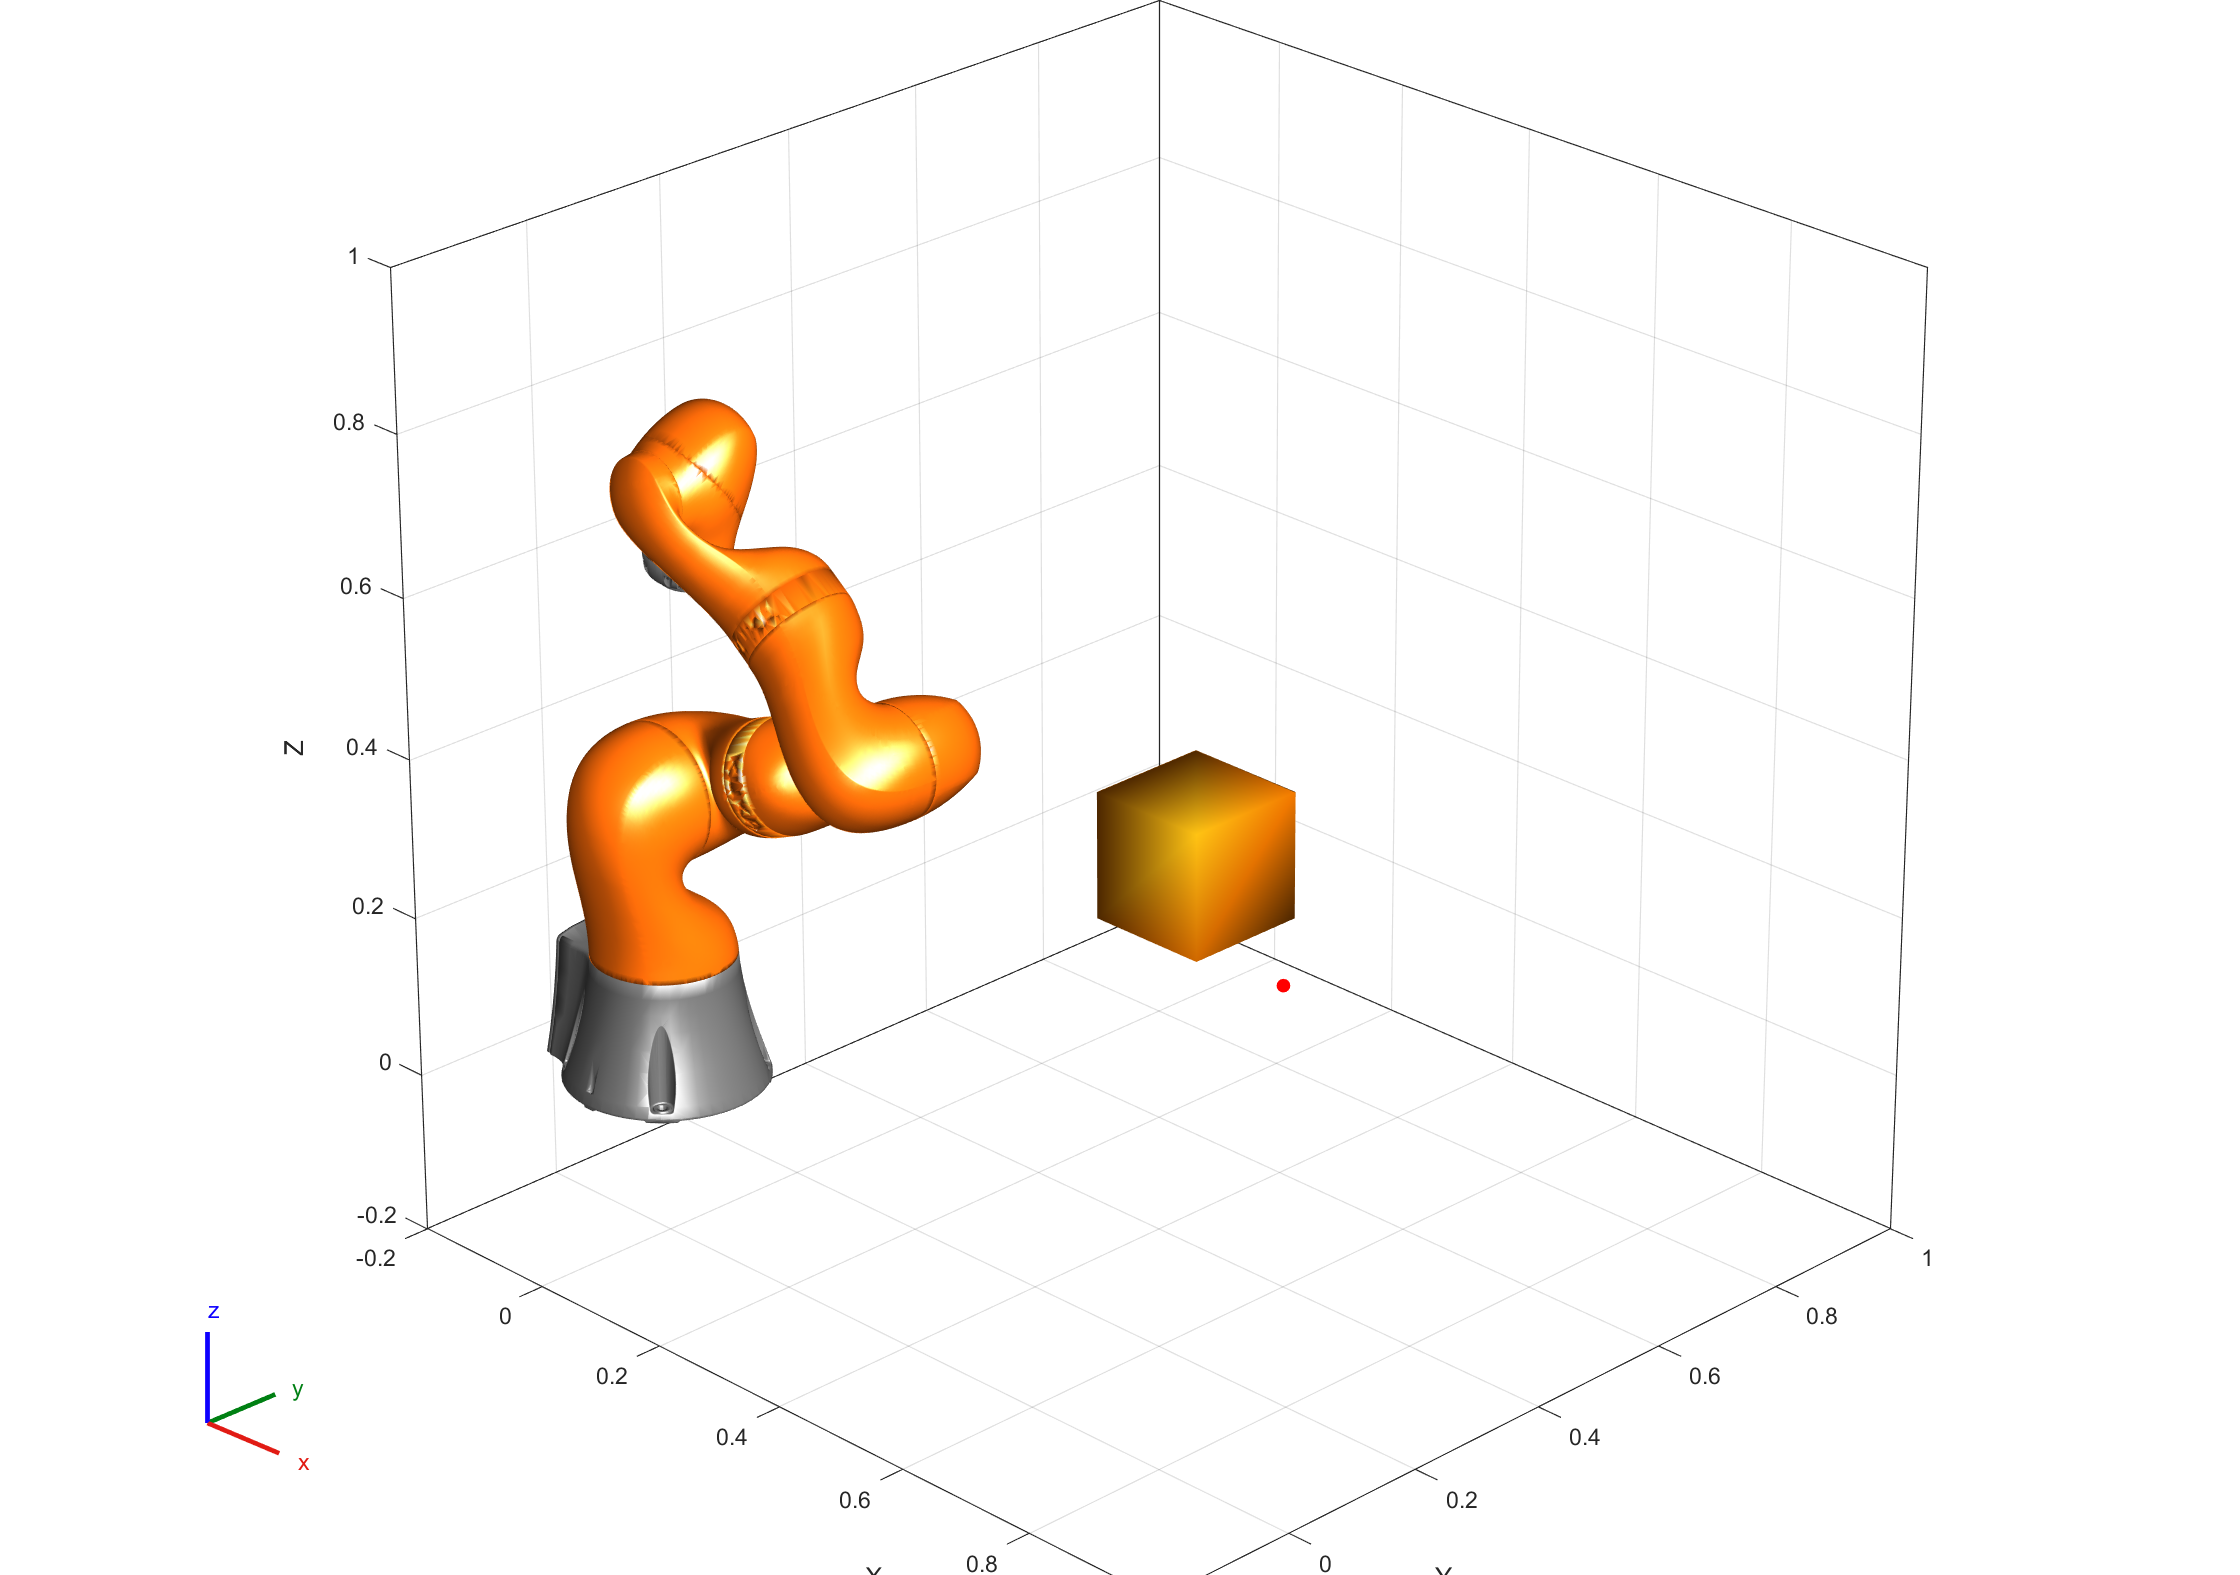

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;
% ==== 放大并规范 3D 视图 ====
fig = gcf; set(fig,'Color','w','Position',[100 100 1280 900]);  % 放大窗口
ax  = gca; view(ax, 45, 25); grid(ax,'on'); box(ax,'on'); hold(ax,'on');
axis(ax,'vis3d'); daspect(ax,[1 1 1]); pbaspect(ax,[1 1 1]);   % 立方比例


xlim(ax,[-0.2, 1]);
ylim(ax,[-0.2, 1]);
zlim(ax,[-0.2, 1]);

camlight(ax,'headlight'); lighting(ax,'gouraud');  % 柔和光照

drawnow;




Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

历时 0.076176 秒。


Qtheta = 14.3550

RAR = 14.3550

Estimated gradient is 0 and Theta is not updated: there could be no obstacle at all
STOMP Finished.


isTrajectoryInCollision = logical
   1


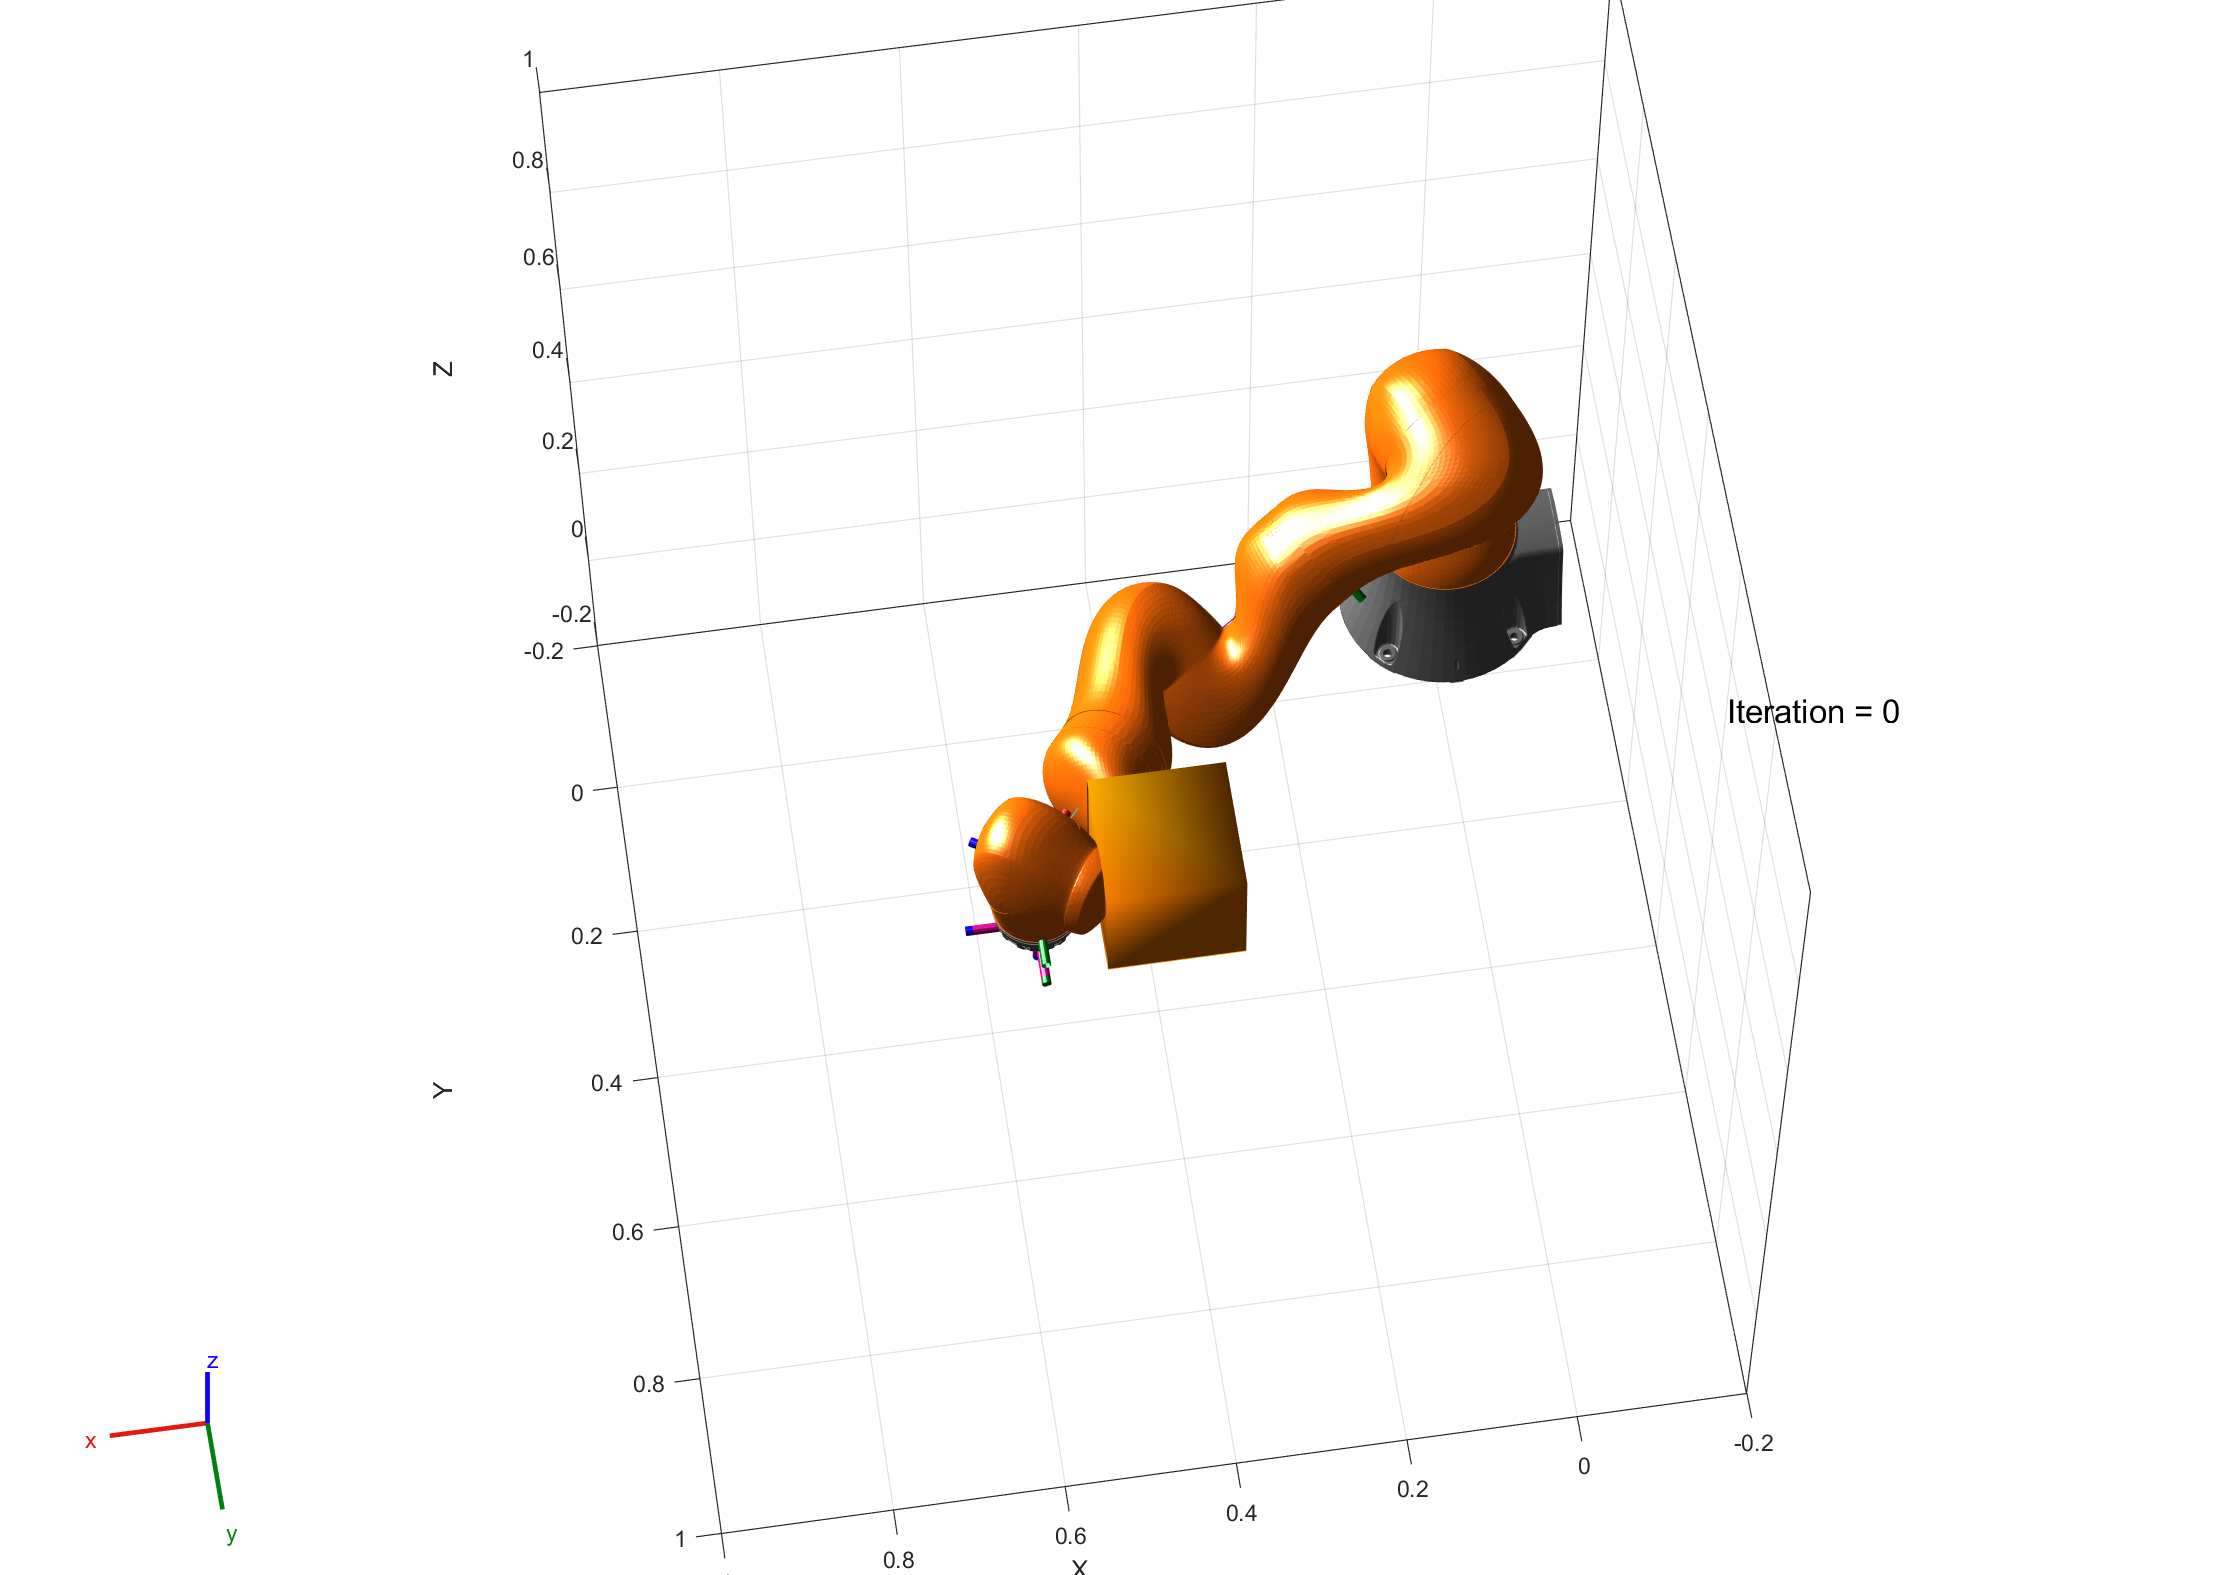

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.